# Segment Image into Three Levels Using Two Thresholds

Read an image, convert it to grayscale, and display the result.

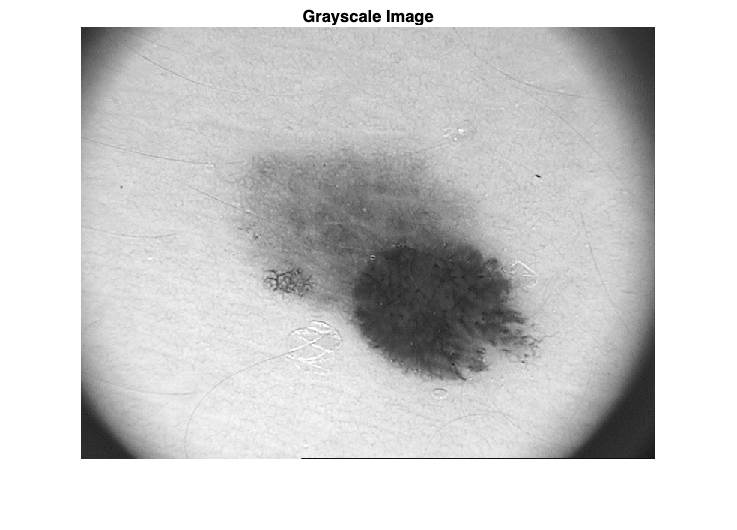

I = imread("Images/Bad/ISIC_0000363.jpg");
I = rgb2gray(I);
imshow(I)
title("Grayscale Image")

Calculate two threshold levels.

thresh = multithresh(I,2);

Segment the image into three levels using the `imquantize` function.

labels = imquantize(I,thresh);

Convert the segmented image into a color image using the `label2rgb` function, and display the image.

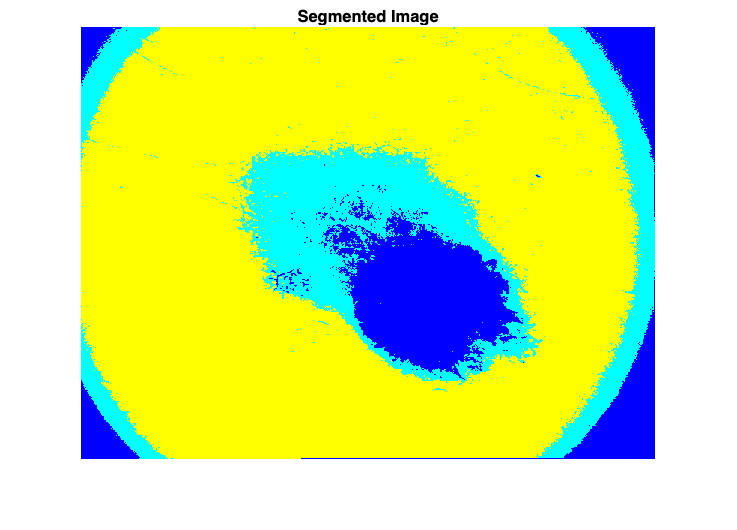

labelsRGB = label2rgb(labels);
imshow(labelsRGB)
title("Segmented Image")

*Copyright 2015 The MathWorks, Inc.*